clear
%%摩擦轮的模型，但不带有共速的模型
V_t=18;
syms E r d F E1 E2 v1 v2 a f m MU R n I l s V_test
eq1 = F == (4/3)*E*sqrt(r)*d^(3/2);
eq2 = 1/E == (1 -v1^2)/E1 + (1 - v2^2)/E2;
eq3 = m*a == 3*f;
eq4 = f == F*MU;
eq5=n==R+r-I;
eq6=(n)^2+(l/2)^2==(R+r)^2;
eq7=(n)^2+(l/2-s)^2==(R+r-d)^2;


sol1 =solve([eq5,eq7,eq6],[d,l,n]);
d_expr=sol1.d(4)

$$d\_expr = R+r-\sqrt{2\,R\,r-2\,s\,\sqrt{\text{I}\,\left(2\,R-\text{I}+2\,r\right)}+R^{2}+r^{2}+s^{2}}$$

l_expr=sol1.l(4)

$$l\_expr = 2\,\sqrt{\text{I}\,\left(2\,R-\text{I}+2\,r\right)}$$


eq8= d==d_expr;

sol2 = solve([eq1, eq2, eq3, eq4,eq8], [a, E, F, f,d]);
a_expr = sol2.a 

$$a\_expr = \frac{4\,E_{1}\,E_{2}\,\mathrm{MU}\,\sqrt{r}\,{\left(R+r-\sqrt{2\,R\,r-2\,s\,\sqrt{\text{I}\,\left(2\,R-\text{I}+2\,r\right)}+R^{2}+r^{2}+s^{2}}\right)}^{3/2}}{m\,\left(-E_{2}\,{v_{1}}^{2}-E_{1}\,{v_{2}}^{2}+E_{1}+E_{2}\right)}$$


eq9=V_t*(R+r-d)/n==V_test

$$eq9 = \frac{18\,R-18\,d+18\,r}{n}=V_{\mathrm{test}}$$

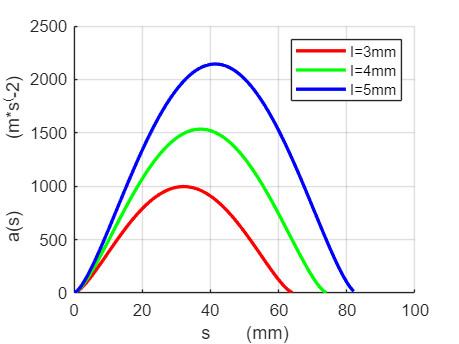


E1_NUM=5e6;%MPa
E2_NUM=20e6;%MPa
v1_NUM=0.3;
v2_NUM=0.3;
R_NUM=(110/2)*(10^-3);%米
r_NUM=119e-3;%米
m_NUM=0.6;%千克
MU_NUM=0.6;




% 定义颜色数组（根据循环次数生成）
I_values = 3e-3:1e-3:5e-3;  % 所有 I 的取值
num_plots = length(I_values);
colors = hsv(num_plots);  % 使用 hsv 颜色映射生成 num_plots 种颜色


    figure;
    hold on;
    grid on;



% 循环绘图:对球的加速度
for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒

    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));


    s_values=0:1:(result_l)*(10^3);
    
    
    plot(s_values, result_a_value, 'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('s       (mm)');
    ylabel('a(s)        (m*s^(-2)');

     
end

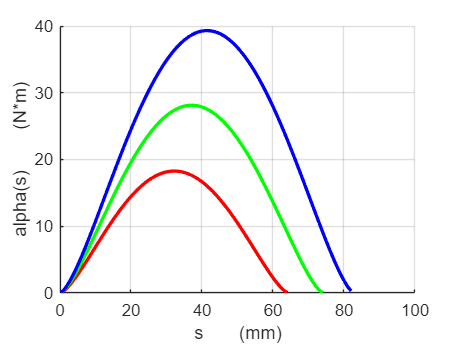



    figure;
    hold on;
    grid on;


% 循环绘图：对单条同步带产生的抵抗力矩
for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    result_alpha=subs(result_a*(R),R,R_NUM);
    s_values=0:0.001:(result_l);
    result_alpha_value=double(subs(result_alpha,s,s_values))/3;
    s_values=0:1:(result_l)*(10^3);



    plot(s_values, result_alpha_value, 'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('s       (mm)');
    ylabel('alpha(s)        (N*m)');

     
end

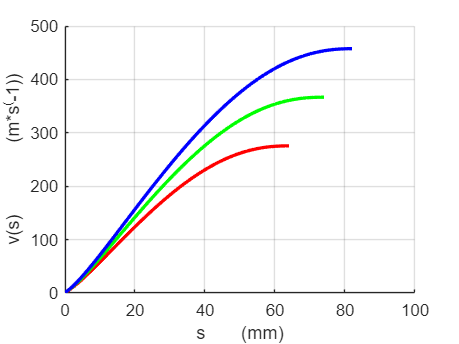


    figure;
    hold on;
    grid on;

% 循环绘图：对球的速度
for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value = 1+(2*cumtrapz(result_a_value)).^(0.5);  % 累积数值积分
    s_values=0:1:(result_l)*(10^3);
    
    
    plot(s_values, result_v_value, 'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('s       (mm)');
    ylabel('v(s)        (m*s^(-1))');

     
end

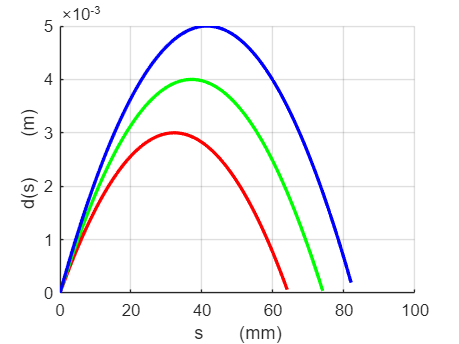

    figure;
    hold on;
    grid on;
% 循环绘图:对同步带的形变量
for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_d=subs(d_expr,[R,r,I],[R_NUM,r_NUM,I_NUM]);

    s_values=0:0.001:(result_l);
   
    result_d_value=subs(result_d,s,s_values);

    s_values=0:1:(result_l)*(10^3);
    
    
    plot(s_values, result_d_value, 'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('s       (mm)');
    ylabel('d(s)        (m)');

     
end

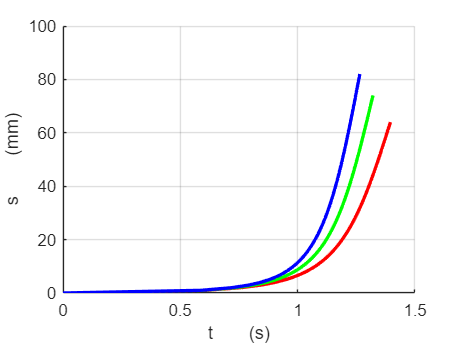



    figure;
    hold on;
    grid on;

%反演时间


for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value =1+ (2*cumtrapz(result_a_value)).^(0.5);  % 对v的累积数值积分
    k = result_v_value ;%给一定的初速度
    result_t=1./k;
    result_t_value=cumtrapz(result_t);

    s_values=0:1:(result_l)*(10^3);

    plot(result_t_value,s_values,'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('t       (s)');
    ylabel('s        (mm)');  
end

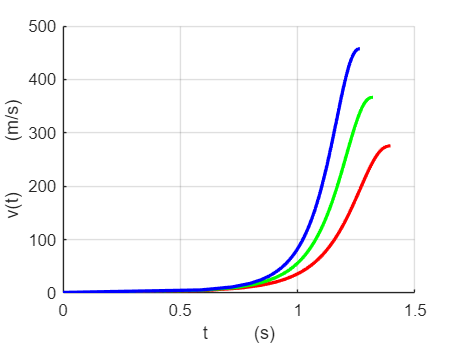





    figure;
    hold on;
    grid on;

%刻画各个参数与时间的关系


for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value = 1+(2*cumtrapz(result_a_value)).^(0.5);  % 对v的累积数值积分
    k = result_v_value ;%给一定的初速度
    result_t=1./k;
    result_t_value=cumtrapz(result_t);

    %s_values=0:1:(result_l)*(10^3);

    plot(result_t_value,result_v_value,'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('t         (s)');
    ylabel('v(t)          (m/s)');  
end

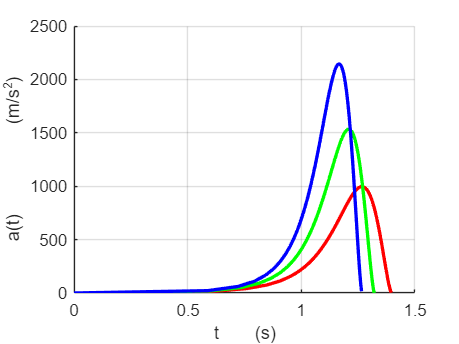



    figure;
    hold on;
    grid on;



for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value = 1+(2*cumtrapz(result_a_value)).^(0.5);  % 对v的累积数值积分
    k = result_v_value ;%给一定的初速度
    result_t=1./k;
    result_t_value=cumtrapz(result_t);

    %s_values=0:1:(result_l)*(10^3);

    plot(result_t_value,result_a_value,'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('t       (s)');
    ylabel('a(t)          (m/s^2)');  
end

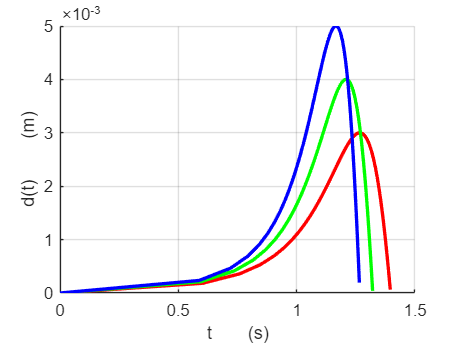





    figure;
    hold on;
    grid on;



for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_d=subs(d_expr,[R,r,I],[R_NUM,r_NUM,I_NUM]);

    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    s_values=0:0.001:(result_l);
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value = 1+(2*cumtrapz(result_a_value)).^(0.5);  % 对v的累积数值积分
    k = result_v_value ;%给一定的初速度
    result_t=1./k;
    result_t_value=cumtrapz(result_t);

   
    result_d_value=subs(result_d,s,s_values);

    %s_values=0:1:(result_l)*(10^3);
    
    
    plot(result_t_value, result_d_value, 'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('t       (s)');
    ylabel('d(t)        (m)');

     
end

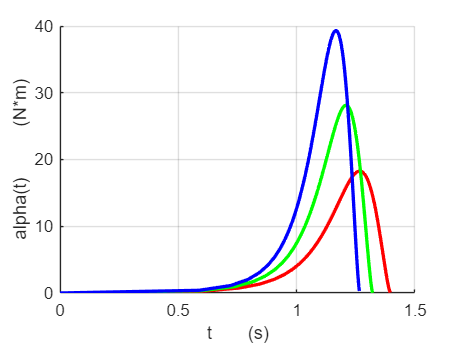




    figure;
    hold on;
    grid on;



for idx = 1:num_plots
    I_NUM = I_values(idx);

    l_num=subs(l_expr,[I,R,r],[I_NUM ,R_NUM,r_NUM]);%单位是米
    result_l=double(l_num);
    result_a=subs(a_expr,[E1,E2,v1,v2,R,r,m,MU,I],[E1_NUM,E2_NUM,v1_NUM,v2_NUM,R_NUM,r_NUM,m_NUM,MU_NUM,I_NUM]);%单位是米每二次方秒
    result_alpha=subs(result_a*(R),R,R_NUM);
    s_values=0:0.001:(result_l);
    result_alpha_value=double(subs(result_alpha,s,s_values))/3;
    result_a_value=double(subs(result_a,s,s_values));
    result_v_value = 1+(2*cumtrapz(result_a_value)).^(0.5);  % 对v的累积数值积分
    k = result_v_value ;%给一定的初速度
    result_t=1./k;
    result_t_value=cumtrapz(result_t);

    %s_values=0:1:(result_l)*(10^3);

    plot(result_t_value,result_alpha_value,'LineWidth', 2,'Color',colors(idx, :),'DisplayName', ['I=',num2str(I_NUM*1e3),'mm']);
    xlabel('t       (s)');
    ylabel('alpha(t)          (N*m)');  
end